clc
clear all

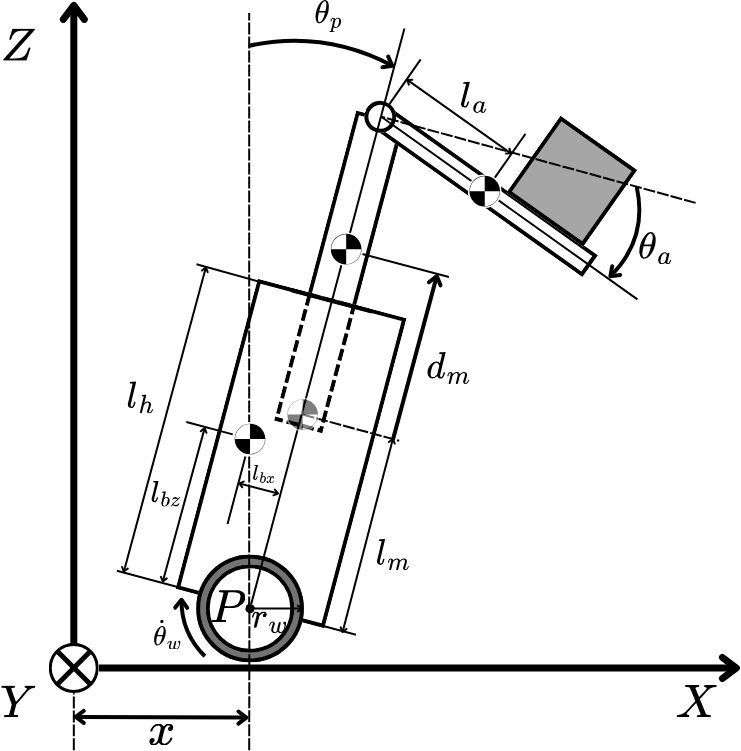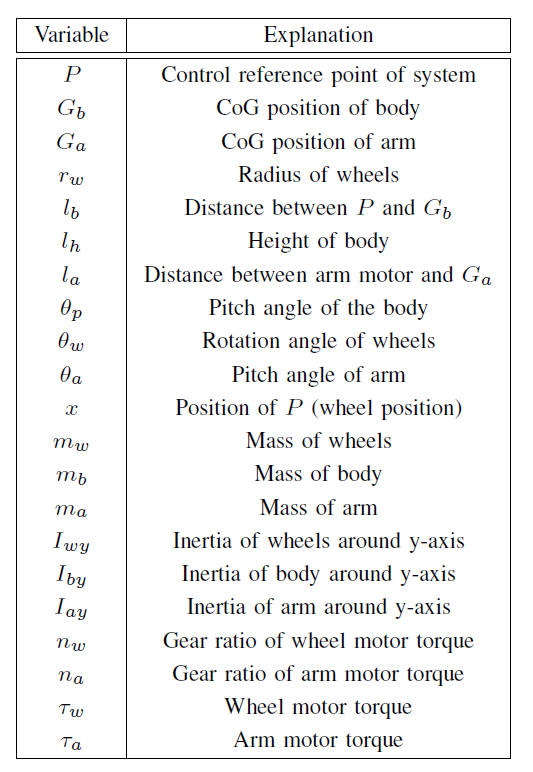

syms t g rw lbz lbx lm lh la d_m(t) dd_m ddd_m th_p(t) dth_p ddth_p th_a(t) dth_a ddth_a th_w(t) dth_w ddth_w mw mb mm ma Iw Ib Im Ia nw na tau_w F_m tau_a


% Rotation matrices for theta_p and theta_a

Rp = simplify([cos(pi/2-th_p(t)) -sin(pi/2-th_p(t));
      sin(pi/2-th_p(t)) cos(pi/2-th_p(t))]);

Ra = [cos(-th_a(t)) -sin(-th_a(t));
      sin(-th_a(t)) cos(-th_a(t))];

% Linear velocity robot
v = [diff(th_w(t))*rw; 0];


% --Wheels--

% Linear velocity
vw = v;

% Angular velocity
ww = v(1)/rw;

% Generalized velocity vector
vtw = [vw; ww];

% Unified inertia
Itw = 2*[mw 0 0;
         0 mw 0;
         0 0 Iw];

% Kinetic energy
Kw = 1/2*vtw.'*Itw*vtw;


% --Body--

% CoG coordinates w.r.t. P
% Gb = Rp*[lbz; 0];
Gb = Rp*[lbz; lbx];
% Angular velocity
wb = diff(th_p);

% Linear velocity
vb = vw+diff(Gb);

% Generalized velocity vector
vtb = [vb; wb];

% Unified inertia
Itb = [mb 0 0;
       0 mb 0;
       0 0 Ib];

% Kinetic energy
Kb = simplify(1/2*vtb.'*Itb*vtb);

% Potential energy
Ub = mb*g*Gb(2);


% --Lift--

% CoG coordinates w.r.t. P
Gm = Rp*[lm+d_m(t); 0];
% Angular velocity
wm = wb;

% Linear velocity
vm = vw+diff(Gm);

% Generalized velocity vector
vtm = [vm; wm];

% Unified inertia
Itm = [mm 0 0;
       0 mm 0;
       0 0 Im];

% Kinetic energy
Km = simplify(1/2*vtm.'*Itm*vtm);

% Potential energy
Um = mm*g*Gm(2);


% --Arm--

% CoG coordinates  w.r.t. P
GaR = simplify(expand(Rp*([lh+d_m(t); 0]+Ra*[0; -la])));

% Angular velocity w.r.t. O
wa = wb + diff(th_a);

% Linear velocity w.r.t. O
va = simplify(vw + diff(GaR));

% Generalized velocity vector
vta = [va; wa];

% Unified inertia
Ita = [ma 0 0;
       0 ma 0;
       0 0 Ia];

% Kinetic energy
Ka = simplify(1/2*vta.'*Ita*vta);

% Potential energy
Ua = ma*g*GaR(2);


%--Total Energy--

% Total U
U = Ub+Um+Ua;

%Total K
K = simplify(expand(Kw+Kb+Km+Ka));


%--Lagrangian--
L = K - U;

% Generalized coordinates
q = [th_w(t), th_p(t), d_m(t), th_a(t)];
dq = [dth_w, dth_p, dd_m, dth_a];
ddq = [ddth_w, ddth_p, ddd_m, ddth_a];

% Preallocate vectors for dL_dq and dL_dt
dL_dq = sym(zeros(length(q), 1)); % Partial derivatives of L w.r.t. q
dL_dt = sym(zeros(length(q), 1)); % Time derivatives of partial derivatives of L w.r.t. dq

% Compute derivatives
for i = 1:length(q)
    % Partial derivative of L with respect to q(i)
    dL_dq(i) = collect(diff(L, q(i)),[diff(q,2), diff(q), q]);
    
    % Partial derivative of L with respect to dq(i)
    dL_ddq = diff(L, diff(q(i)));
    
    % Time derivative of the above partial derivative
    dL_dt(i) = collect(diff(dL_ddq, t),[diff(q,2), diff(q), q]);
end

% Generalized torques
tau = [nw*tau_w; -nw*tau_w; F_m; na*tau_a];

% Euler-Lagrange equation
EL_eq = dL_dt-dL_dq == tau;

% Find inertia matrix
M = subs(EL_eq,[diff(q,2), diff(q), g],[ddq, zeros(1,length(q)), 0]);
M = equationsToMatrix(M,ddq);
M = collect(simplify(expand(M)),[mw mb mm ma Iw Ib Im Ia])


% Find coriolis and centripetal matrix
H = lhs(subs(EL_eq,[diff(q,2), diff(q), g],[zeros(1,length(q)), diff(q), 0]));
H = simplify(expand(H))


% Find gravitational matrix
G = lhs(subs(EL_eq,[diff(q,2), diff(q), g],[zeros(1,length(q)), zeros(1,length(q)), g]));
G = simplify(G)

$$G = \begin{array}{l} \left(\begin{array}{c} 0\\ g\,\mathrm{mb}\,\left(\mathrm{lbx}\,\cos\left({\mathrm{th}}_{p}\left(t\right)\right)-\mathrm{lbz}\,\sin\left({\mathrm{th}}_{p}\left(t\right)\right)\right)-g\,\mathrm{ma}\,\left(\mathrm{lh}\,\sin\left({\mathrm{th}}_{p}\left(t\right)\right)+\mathrm{la}\,\sigma_{1}\right)-g\,\sin\left({\mathrm{th}}_{p}\left(t\right)\right)\,d_{m}\left(t\right)\,\left(\mathrm{ma}+\mathrm{mm}\right)-g\,\mathrm{lm}\,\mathrm{mm}\,\sin\left({\mathrm{th}}_{p}\left(t\right)\right)\\ g\,\cos\left({\mathrm{th}}_{p}\left(t\right)\right)\,\left(\mathrm{ma}+\mathrm{mm}\right)\\ -g\,\mathrm{la}\,\mathrm{ma}\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left({\mathrm{th}}_{a}\left(t\right)+{\mathrm{th}}_{p}\left(t\right)\right) \end{array}$$